## Exemples preprocesament

Revisant el dataset, podem veure que bàsicament els problemes que podem tenir son la lluminositat i el desenfoc

brillant = imread('D:\Documents\VC-MiniProject\Train1\Train1\1\00001_00000_00029.png');
%imshow(brillant);

obscura = imread('D:\Documents\VC-MiniProject\Train1\Train1\1\00001_00012_00025.png');
%imshow(obscura);

%desenfocada = imread('D:\Documents\VC-MiniProject\Train1\Train1\1\00001_00013_00022.png');
%montage({brillant, obscura, desenfocada});

Mirant els dos histogrames pels casos de brillantor/obscuritat podem veure:

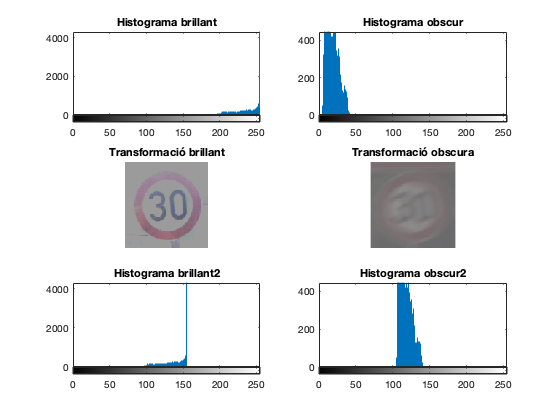

%filas de cuadricula, columnas cuadricula, posición actual:
figure;
subplot(3,2,1)
imhist(brillant);
title("Histograma brillant");

subplot(3,2,2)
imhist(obscura);
title("Histograma obscur");

subplot(3,2,3)
brillant2 = arrayfun(@(x) x-100,brillant);
imshow(brillant2);
title("Transformació brillant");

subplot(3,2,4)
obscura2 = arrayfun(@(x) x+100, obscura);
imshow(obscura2);
title("Transformació obscura");

subplot(3,2,5)
imhist(brillant2);
title("Histograma brillant2");

subplot(3,2,6)
imhist(obscura2);
title("Histograma obscur2");

Hem aplicat uns valors arbitraris, l'objectiu era "centrar" l'histograma. Ara intentem que aquets valors no siguin arbitraris, sino que estiguin relacionats amb l'imatge a tractar.

http://homepages.inf.ed.ac.uk/rbf/HIPR2/stretch.htm

brillantN = normalizeImage(brillant);
obscuraN = normalizeImage(obscura);

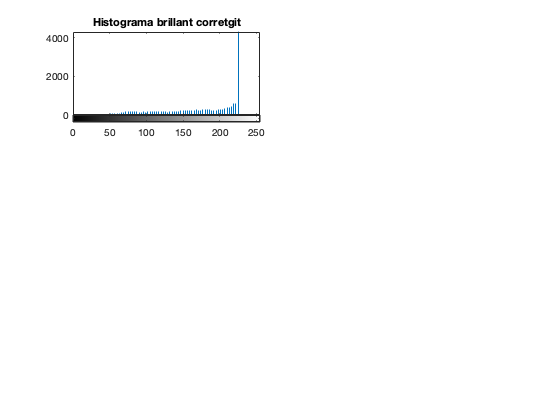

figure;
subplot(3,2,1)
imhist(brillantN);
title("Histograma brillant corretgit");

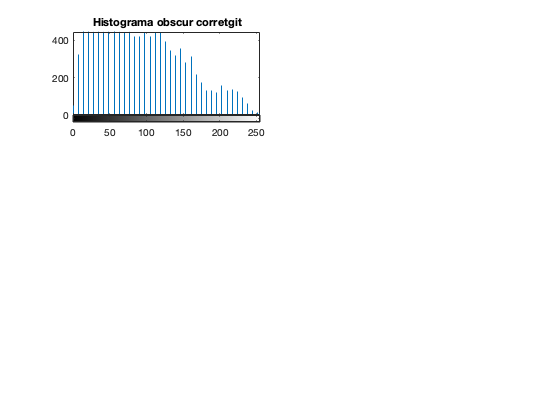


subplot(3,2,1)
imhist(obscuraN);
title("Histograma obscur corretgit");

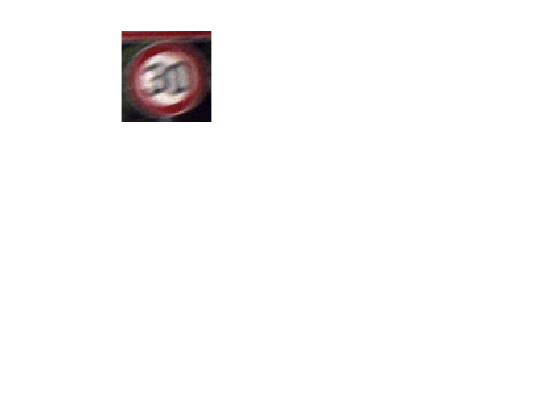


imshow(obscuraN);

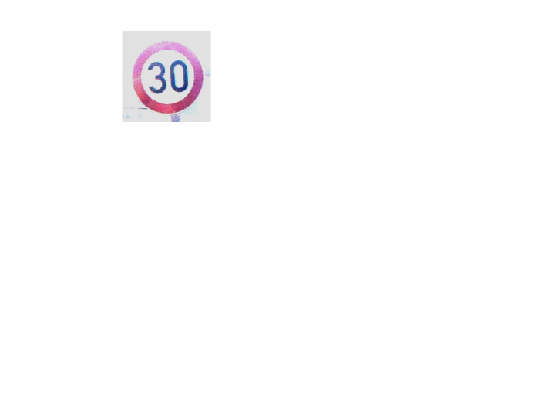

imshow(brillantN);